data = readtable('C:\Users\USER\Downloads\diabetes.csv');
X = table2array(data(:, 1:end-1));
Y = table2array(data(:, end));

%X = normalize(X, 'range');

cv = cvpartition(size(X,1), 'HoldOut', 0.3);
idx = cv.test;
XTrain = X(~idx, :);
YTrain = Y(~idx, :);
XTest = X(idx, :);
YTest = Y(idx, :);

fis2 = genfis2(XTrain, YTrain, 0.4);


epoch_n = 50;
anfis_model2 = anfis([XTrain YTrain], fis2, epoch_n);

ANFIS info:
	Number of nodes: 101
	Number of linear parameters: 45
	Number of nonlinear parameters: 80
	Total number of parameters: 125
	Number of training data pairs: 538
	Number of checking data pairs: 0
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 0.380241

Designated epoch number reached. ANFIS training completed at epoch 1.

Minimal training RMSE = 0.380241



yPred2 = evalfis(XTest, anfis_model2);

yPred2 = round(yPred2);
accuracy2 = sum(yPred2 == YTest) / length(YTest);
fprintf('ANFIS (genfis2) Accuracy: %.2f%%\n', accuracy2 * 100);

ANFIS (genfis2) Accuracy: 79.13%


anfis_model2 = anfis([XTrain YTrain], fis2, epoch_n);

ANFIS info:
	Number of nodes: 101
	Number of linear parameters: 45
	Number of nonlinear parameters: 80
	Total number of parameters: 125
	Number of training data pairs: 538
	Number of checking data pairs: 0
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 0.380241

Designated epoch number reached. ANFIS training completed at epoch 1.

Minimal training RMSE = 0.380241


showrule(anfis_model2)

ans = 5×233 char array
    '1. If (in1 is in1cluster1) and (in2 is in2cluster1) and (in3 is in3cluster1) and (in4 is in4cluster1) and (in5 is in5cluster1) and (in6 is in6cluster1) and (in7 is in7cluster1) and (in8 is in8cluster1) then (out1 is out1cluster1) (1)'
    '2. If (in1 is in1cluster2) and (in2 is in2cluster2) and (in3 is in3cluster2) and (in4 is in4cluster2) and (in5 is in5cluster2) and (in6 is in6cluster2) and (in7 is in7cluster2) and (in8 is in8cluster2) then (out1 is out1cluster2) (1)'
    '3. If (in1 is in1cluster3) and (in2 is in2cluster3) and (in3 is in3cluster3) and (in4 is in4cluster3) and (in5 is in5cluster3) and (in6 is in6cluster3) and (in7 is in7cluster3) and (in8 is in8cluster3) then (out1 is out1cluster3) (1)'
    '4. If (in1 is in1cluster4) and (in2 is in2cluster4) and (in3 is in3cluster4) and (in4 is in4cluster4) and (in5 is in5cluster4) and (in6 is in6cluster4) and (in7 is in7cluster4) and (in8 is in8cluster4) then (out1 is out1cluster4) (1)'
    '5. If (in1 i

rules = fis2.Rules;
nRules = numel(rules);
nInputs = numel(fis2.Inputs);
r = 1

r = 1

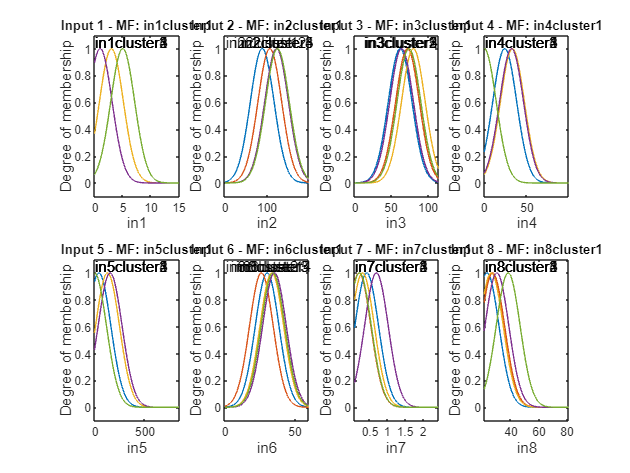

    figure('Name', ['Rule ' num2str(r)]);
    for i = 1:nInputs
        mfIndex = rules(r).Antecedent(i);
        mf = fis2.Inputs(i).MembershipFunctions(mfIndex);
        subplot(2, ceil(nInputs/2), i)
        plotmf(fis2, 'input', i)
        title(sprintf('Input %d - MF: %s', i, mf.Name))
        hold on
    end

input_names = {'Pregnancies', 'Glucose', 'BloodPressure', ...
               'SkinThickness', 'Insulin', 'BMI', ...
               'DiabetesPedigreeFunction', 'Age'};

mf_labels = {'Low', 'Medium', 'High'};

rules = anfis_model2.rule;
numRules = length(rules);

fprintf('\n======= ANFIS Extracted Rules =======\n\n');


======= ANFIS Extracted Rules =======




for i = 1:numRules
    rule = rules(i);
    str = sprintf('Rule %d: IF ', i);
    
    for j = 1:length(rule.antecedent)
        mf_index = rule.antecedent(j);
        if mf_index == 0
            continue;
        end
        if mf_index > length(mf_labels)
            mf_text = sprintf('MF%d', mf_index);
        else
            mf_text = mf_labels{mf_index};
        end
        str = [str, sprintf('(%s is %s)', input_names{j}, mf_text)];
        if j < length(rule.antecedent)
            str = [str, ' AND '];
        end
    end
    
    output_value = rule.consequent;
    if output_value == 1
        out_text = 'No Diabetes';
    else
        out_text = 'Diabetes';
    end
    
    str = [str, sprintf(' THEN Output is %s\n', out_text)];
    fprintf('%s', str);
end

Rule 1: IF (Pregnancies is Low) AND (Glucose is Low) AND (BloodPressure is Low) AND (SkinThickness is Low) AND (Insulin is Low) AND (BMI is Low) AND (DiabetesPedigreeFunction is Low) AND (Age is Low) THEN Output is No Diabetes
Rule 2: IF (Pregnancies is Medium) AND (Glucose is Medium) AND (BloodPressure is Medium) AND (SkinThickness is Medium) AND (Insulin is Medium) AND (BMI is Medium) AND (DiabetesPedigreeFunction is Medium) AND (Age is Medium) THEN Output is Diabetes
Rule 3: IF (Pregnancies is High) AND (Glucose is High) AND (BloodPressure is High) AND (SkinThickness is High) AND (Insulin is High) AND (BMI is High) AND (DiabetesPedigreeFunction is High) AND (Age is High) THEN Output is Diabetes
Rule 4: IF (Pregnancies is MF4) AND (Glucose is MF4) AND (BloodPressure is MF4) AND (SkinThickness is MF4) AND (Insulin is MF4) AND (BMI is MF4) AND (DiabetesPedigreeFunction is MF4) AND (Age is MF4) THEN Output is Diabetes
Rule 5: IF (Pregnancies is MF5) AND (Glucose is MF5) AND (BloodPressu